# Frequency Resolution of the DFT

This live script is based on the discussion in MATLAB Exercise 7.6 of 

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

Consider the length-$32$ multi-tone signal


$$x[n] = \cos(0.8345n)+\cos(0.9327n)\,,\quad n=0,\ldots,31$$


Compute and graph the DFT of this signal with or without zero padding.

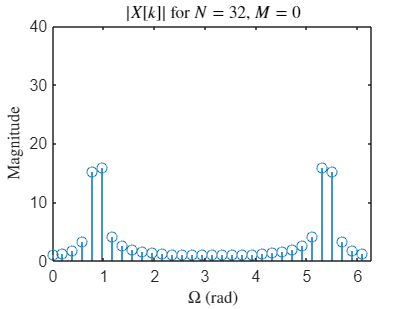

n = [0:31];
xn = cos(17*pi/64*n)+cos(19*pi/64*n);   % 32 samples of the signal
set(0,'defaultTextInterpreter','latex');
graphDFT(xn,32,0);    % No zero padding

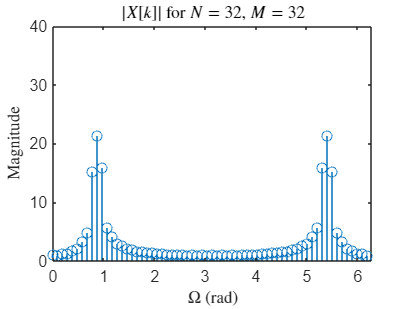

graphDFT(xn,32,32);   % Zero padding by 32 samples

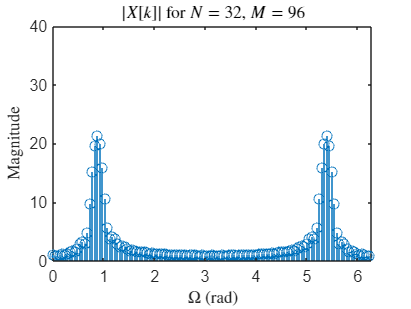

graphDFT(xn,32,96);   % Zero padding by 96 samples

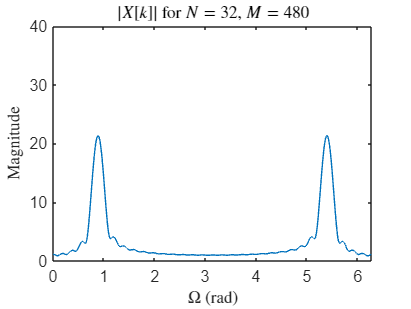

graphDFT(xn,32,480);  % Zero padding by 480 samples

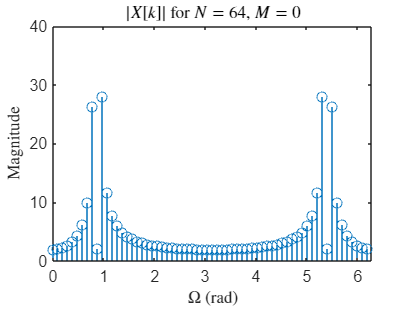

n = [0:63];
xn = cos(17*pi/64*n)+cos(19*pi/64*n);   % 64 samples of the signal
graphDFT(xn,64,0);    % No zero padding

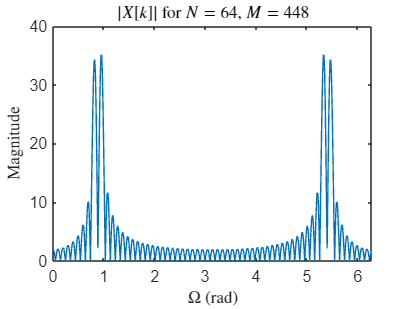

graphDFT(xn,64,448);  % Zero padding by 448 samples

set(0,'defaultTextInterpreter','tex');

function graphDFT(xn,N,M)
  % Local function to compute and graph the DFT
  DFTSize = N+M;
  k = [0:DFTSize-1];
  Omega = 2*pi*k/DFTSize;
  Xk = fft(xn,DFTSize);
  if (DFTSize<256)
    stem(Omega,abs(Xk));
  else
    plot(Omega,abs(Xk));
  end;
  axis([0,2*pi,0,40]);
  tmpstr = "$|X[k]|$  for  $N=$"+N+", $M=$"+M;
  title(tmpstr);
  xlabel('$\Omega$ (rad)');
  ylabel('Magnitude'); 
end